# Bug * Algorithm

## Bug 1

***NOTE:***

- ***Unknown position of obstacles;***

- ***Known position of the goal;***

- ***Sensing (wall/obstacle detection, encorders).***

1) In this kind of exercise we first consider if the goal is on a straight line from the start point. If it is (no object detected then we go to it, otherwise (an obstacle is sensed) we navigate to the obstacle in a straight line that points towards the goal;

2) Then we go around the obstacle once, to then return to the **nearest point to the goal;**

3) Go back to point 1.

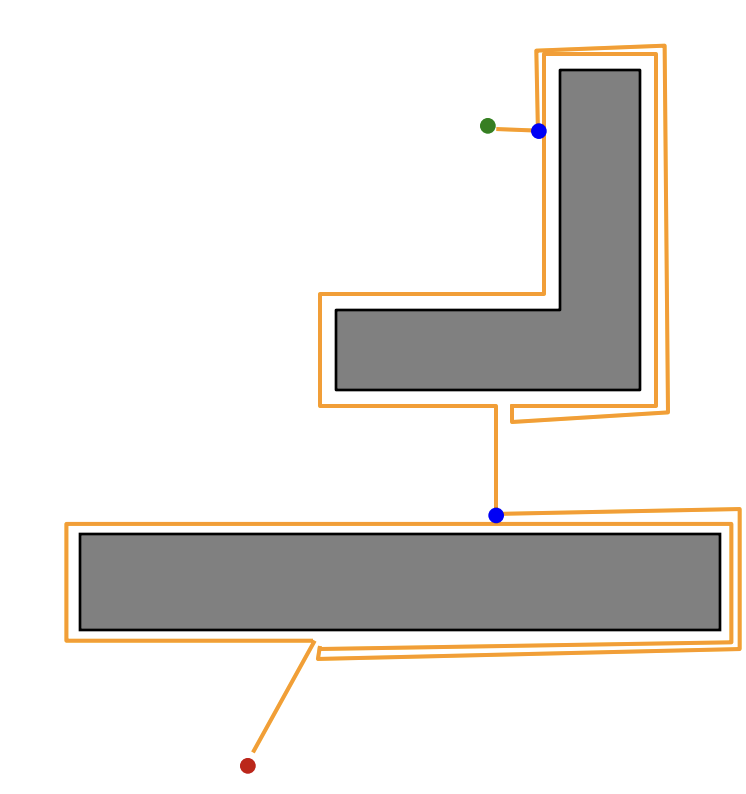

### Bug 1 n.26 2018

clear all
close all
clc

% The robot first circumnavigate around the object than goes back to the
% point of smallest distance to the object

% Thus the robot:
% gets to x = 0.65
% goes around the obstacle going back to  x = 0.65
% goes back again to x = 0.95
% proceeds to x = 1.4


goal = 1.4000

goal = 1.4

radius_obst = 0.1500

radius_obst = 0.15


distance = 2.5137

distance = goal - 2*radius_obst + 3*pi*radius_obst


### Bug 1 n.20 2019

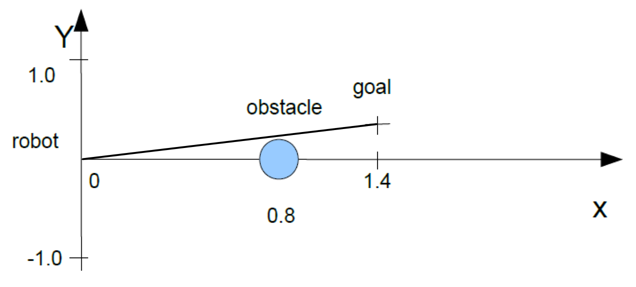

clear all
close all
clc

% In this case the obstacle is not on the line that connects the goal and
% the starting point, hence we can navigate to it in a straight line:

goal = [1.4, 0.3];
center_obst = [0.8, 0];

distance = sqrt(goal(1)^2 + goal(2)^2)

distance =    1.431782106327635


Let's prove that the line doesn't touch the circle:

format short
syms x 
% equation of line:
y(x) = (goal(2) - 0)/(goal(1)- 0)*x

$$y(x) = \frac{3\,x}{14}$$

eval(y(0.8))

ans = 0.1714

As we can see at x = 0.8 the line is at y = 0.17, so above the circle. Thus the robot will not run into the obstacle at all.

### Bug 1 n.20 2021

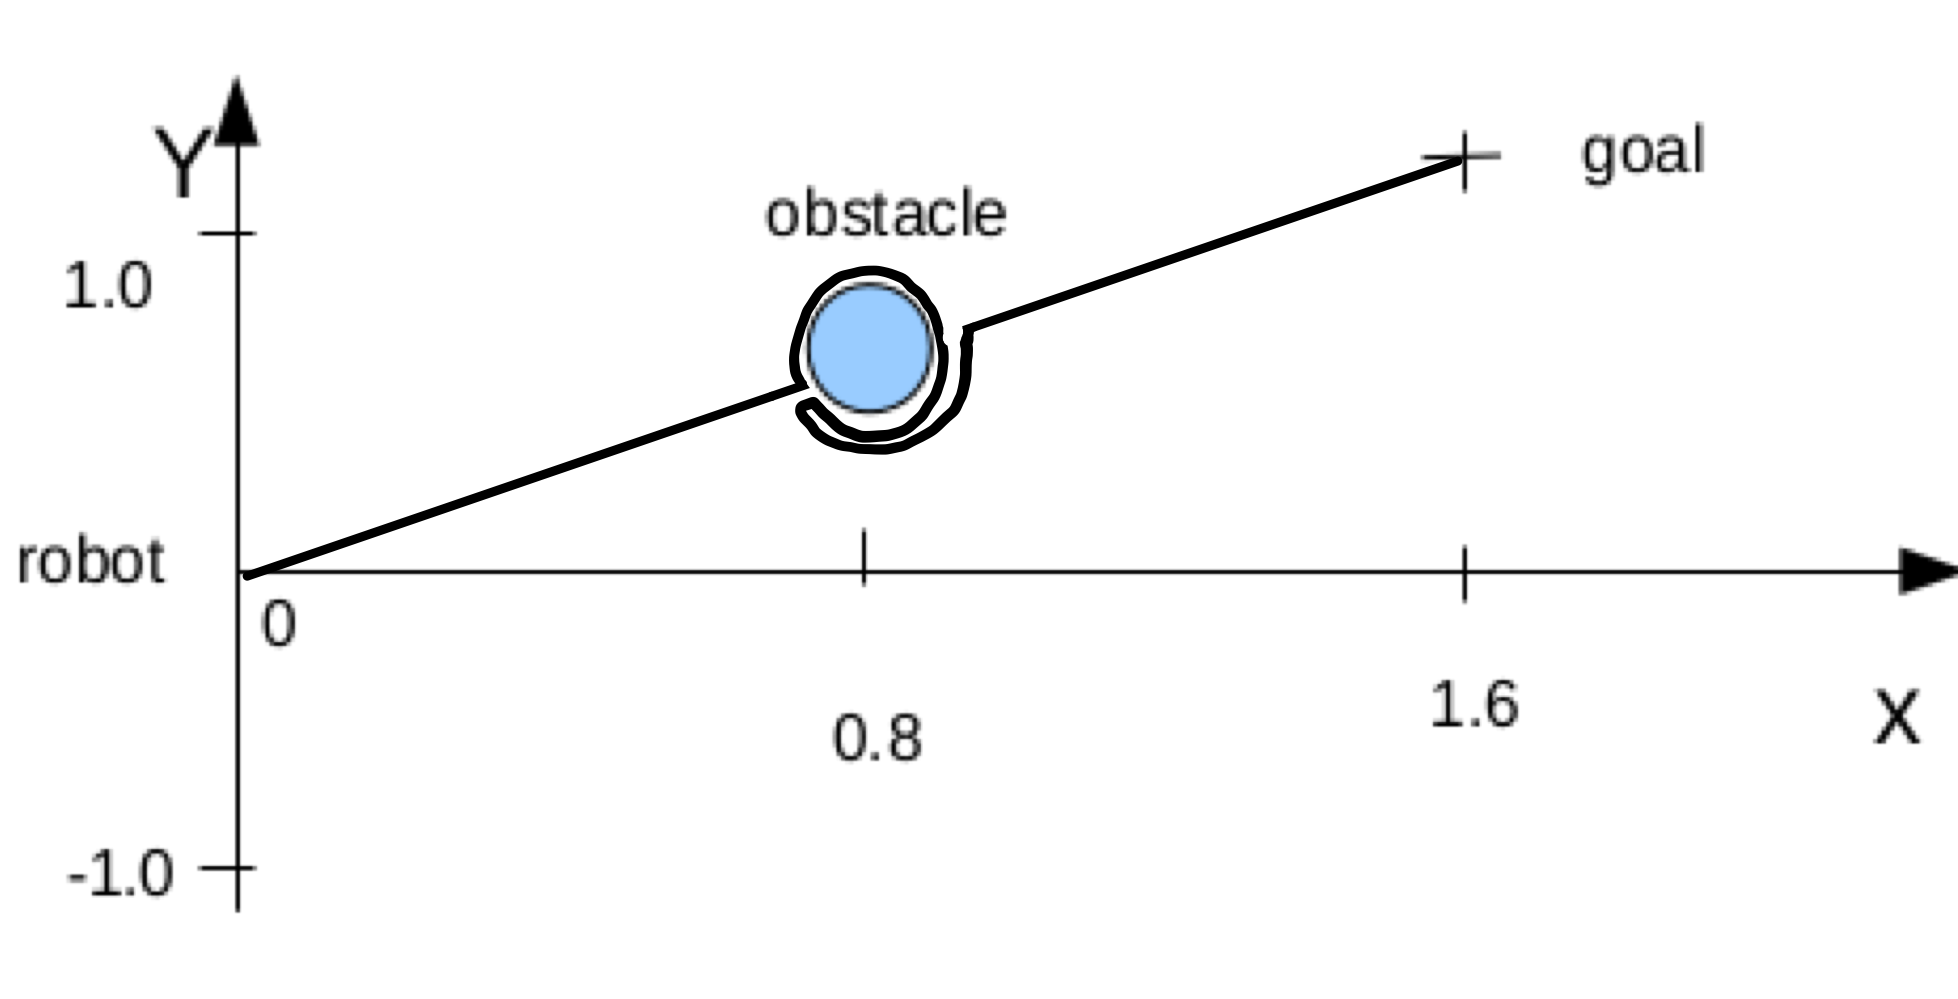

In figure this is how the algorith is supposed to behave.

Hence we must find first  the line  (0,0;1.6,1.2) and then substract two times the radius and add 1.5 times the circumference of the circle.

clear all
close all
clc

format short

goal = [1.6,1.2];
radius_obst = 0.10;

% distance start-goal:
direct_path = sqrt(goal(1)^2+goal(2)^2);


direct_path =      2


% Distance that the algorith will end up with:
distance = direct_path - 2*radius_obst + 3*pi*radius_obst

distance =    2.742477796076938
